# IAVSD23 - Optimizing rail maintenance (v2.0)

Version 3.1 considers natural wear besides the H-index but only within one year

Moreover, the average gauge widening is now variable (rate is no constant anymore).

## Input data (e.g., lookup tables for H-index and natural wear)

clearvars % clear all variables in the workspace

%%% Lookup tables (sheet names in the excel input file)
tonnage = "H_32t";% standard axle load (30 tons), alternatively "H_32t" for heavy axle load (32.5 tons)

%%% Given the axle load, read H-indices, natural wear and gauge widening in the lookup tables for both MB5 and MB6
[H_table_MB5,~,nat_wear_MB5,~,risk_MB5,~, gauge_widening] = read_input_data(tonnage);

%%% plot table
% plot_figure('H_table5_heatmap', H_table_MB5);

## Interpolation and preprocessing for MB5

%%% set interpolation method
interpolation_method = 'linear';% alternatively, 'linear'

%%% set the maximal frequency for grinding activity
grinding_freq_max = 12; % in months, i.e., max number of months beforing grinding (note that wear extrapolation becomes incorrect beyond 12 months)

%%% interpolations of H_table (arg_num = -1) for MB5
H_interpolated_MB5 = interpolation(H_table_MB5,interpolation_method, grinding_freq_max, -1);

%%% interpolation of natural wear table (arg_num = 1) for MB5
NW_interpolated_MB5 = interpolation(nat_wear_MB5,interpolation_method, grinding_freq_max, 1);

%%% interpolation of gauge widening (arg_num = 0)
gauge_widening = interpolation(gauge_widening,interpolation_method, grinding_freq_max, 0);

%%% visualize the interpolated H_tables (and the average monthly deterioration in H-index)
% plot_figure(strcat(interpolation_method,' interpolation'), H_interpolated_MB5)

%%% visualize the interpolated natural wear table (and the average monthly deterioration)
% plot_figure(strcat(interpolation_method,' interpolation'), NW_interpolated_MB5)

%%% get maximal lifetimes
[max_lifetime_MB5] = get_max_lifetime(risk_MB5);

## Finding the optimal maintenance strategy (yearly nb of grindings and tampings)

%%% set paramters for optimization
tamping_freq_max = 48; % maximum number of months before tamping, 48m = 4 years
initial_gauge_widening = 3; % initial yearly gauge widening, e.g., 1, 2 or 3 mm/year,
renewal_costs_MB5 = 1500; % SEK per meter of rail

%%% find optimal strategy, minimal annuity and optimal lifetime
% [opt_grinding, opt_tamping, min_ANN, opt_lifetime] = get_optimal(H_interpolated_MB5, NW_interpolated_MB5, interpolation_method, gauge_widening(:,initial_gauge_widening), max_lifetime_MB5, tamping_freq_max, renewal_costs_MB5)

## Sensitivity analysis

### Renewal costs

%%% set paramters for optimization
initial_gauge_widening = 2; % initial yearly gauge widening, e.g., 1, 2 or 3 mm/year,
nb_points = 7;
rc = linspace(.5,1.5,nb_points)*renewal_costs_MB5;
ANNs = zeros(nb_points,1);
lifetimes = zeros(nb_points,1);
opt_grinding = zeros(nb_points,1);
opt_tamping = zeros(nb_points,1);
for i=1:nb_points
    [opt_grinding(i), opt_tamping(i), ANNs(i), lifetimes(i)] = get_optimal(H_interpolated_MB5, NW_interpolated_MB5, interpolation_method, gauge_widening(:,initial_gauge_widening), max_lifetime_MB5, tamping_freq_max, rc(i));
end

%%% plot the resulting sensitivity analysis
% plot_figure('sensitivity analysis - renewal costs', {opt_grinding, opt_tamping, ANNs, lifetimes, rc});

### Gauge widening

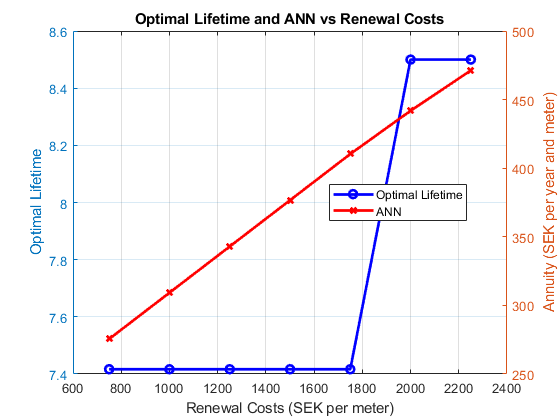

%%% set paramters
nb_gauge_widening = 3;
ANNs = zeros(1,nb_gauge_widening);
lifetimes = zeros(1,nb_gauge_widening);
opt_grinding = zeros(1,nb_gauge_widening);
opt_tamping = zeros(1,nb_gauge_widening);
for gw=1:nb_gauge_widening
    [opt_grinding(gw), opt_tamping(gw), ANNs(gw), lifetimes(gw)] = ...

        get_optimal(H_interpolated_MB5, NW_interpolated_MB5, interpolation_method, gauge_widening(:,gw), max_lifetime_MB5, tamping_freq_max, renewal_costs_MB5);
end

%%% plot the resulting sensitivity analysis
% plot_figure('sensitivity analysis - gauge widening', {opt_grinding, opt_tamping, ANNs, lifetimes});